Q.1 Methods Test , Table and Plot

format long;
% Define input values
n_values = 1:20; % Updated n_values to range from 1 to 20
x_values = [1, 5]; % Example x_values

% Initialize a cell array to represent the table
T = {'n', 'Method_A_x1', 'Method_B_x1', 'Method_A_x5', 'Method_B_x5', 'Error_x1', 'Error_x5'}; % Header row

% Iterate over n_values to calculate results for each n
for i = 1:length(n_values)
    n = n_values(i);

    % Calculate results using Method A (calculate_integrals)
    methodA_x1 = calculate_integrals(n, 1); % Call calculate_integrals for x = 1
    methodA_x5 = calculate_integrals(n, 5); % Call calculate_integrals for x = 5

    % Calculate results using Method B (IntegralIterado)
    %n=0 not included in the table, even though its calculated and necessary
    %for the recursion of the method
        methodB_x1 = IntegralIterado(n+1, 1); % Call IntegralIterado for x = 1
        methodB_x5 =IntegralIterado(n+1, 5); % Call IntegralIterado for x = 5

    % Calculate errors between Method A and Method B
    error_x1 = abs(methodA_x1 - methodB_x1);
    error_x5 = abs(methodA_x5 - methodB_x5);

    % Append the row to the table
    T = [T; {n, methodA_x1, methodB_x1, methodA_x5, methodB_x5, error_x1, error_x5}];
end

% Convert the cell array to a table for better formatting
T = cell2table(T(2:end, :), 'VariableNames', string(T(1, :)));

% Display the table
disp(T);

    n        Method_A_x1           Method_B_x1           Method_A_x5          Method_B_x5             Error_x1                Error_x5      
    __    __________________    __________________    _________________    _________________    ____________________    ____________________

     1    -0.735758882342885    -0.735758882342885     -23.747722563692     -23.747722563692    1.11022302462516e-16     3.5527136788005e-15
     2     0.878884622601834     0.878884622601833     20.1821952056387     20.1821952056387    3.33066907387547e-16                       0
     3    -0.449507401824987    -0.449507401824987    -17.5746622865319    -17.5746622865319     4.9960036108132e-16                       0
     4     0.552372779987656     0.552372779987654      

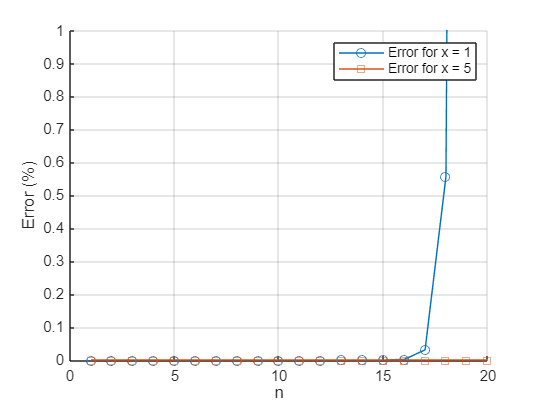


% Extract n, Error_x1, and Error_x5 from the table
n = T.n;
if iscell(T.Error_x1)
    error_x1 = cell2mat(T.Error_x1);
else
    error_x1 = T.Error_x1;
end

if iscell(T.Error_x5)
    error_x5 = cell2mat(T.Error_x5);
else
    error_x5 = T.Error_x5;
end

% Create a figure for the plot
figure;
hold on;

% Plot error for x = 1
plot(n, error_x1, '-o', 'DisplayName', 'Error for x = 1');

% Plot error for x = 5
plot(n, error_x5, '-s', 'DisplayName', 'Error for x = 5');

% Add labels, legend, and title
xlabel('n');
ylabel('Error (%)');
legend('show');
grid on;

% Set y-axis limits to 1%
ylim([0 1]);

hold off;

Q.2 Methods Test , Table and Plot